## Bending Moment Calculator

### Purpose:

The purpose of this calculator is to calculate the maximum bending moment magnitude and location on the vehicle. It utilizes the Barrowman approximations to define the aerodynamic forces. It assumes that the nosecone shape is Von Karman (affects cp location). Barrowman method also neglects compressibility effects at supersonic speeds, but it is conservative so good approximation.

### Inputs:

- Fully defined vehicle geometry

- Burnout velocity

### Outputs:

- Max drag force

- Max dynamic pressure

- Center of pressure location

- Lateral acting inertia loads

- Shear and Bending diagrams

## Inputs

Please manually change the following numbers. The following diagram should be used for fin geometry.

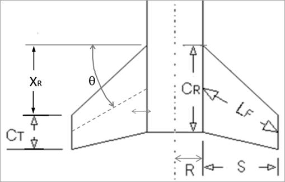

% Yield Stress of Material (at max compressive force location) (psi)
% You will have to run the calculator once and then update this value
Fy = 35000;
% Air Density at burnout alt (lbm/ft^3)
rho = 0.00221;
% Burnout Velocity (ft/s) (Burnout Altitude: 2527 ft)
burn_v = 1230;
% Maximum Acceleration (ft/s^2)
a_max = 670;
% Vehicle Wet Mass (lb)
m_wet = 13.69;
% Coefficient of Drag
cd = 0.721;
% Vehicle Outer Diameter (in)
d = 3.12;
% Airframe Wall Thickness (in)
t = 0.06;
% Angle of Attack (rad) (usually 5-10 deg for worst case)
aoa = 0.175;
% Fin Geometry (in)
N = 3;   %number of fins
R = 1.5;
S = 4.5;
Xr = 5.5;
Ct = 1.5;
Cr = 6;
% Cn_alpha for nosecone (find in OpenRocket) (rad^-1)
Cn_alpha_nose = 2.861;
% Distance from tip of nosecone to start of fins (in)
xb = 75.482;
% Nosecone length (in)
L_nose = 17.25;
% Cg location from tip of nosecone (in)
Xcg = 49.806;

### Calculations and Outputs

The following image is used for reference for lateral acting inertial loads.

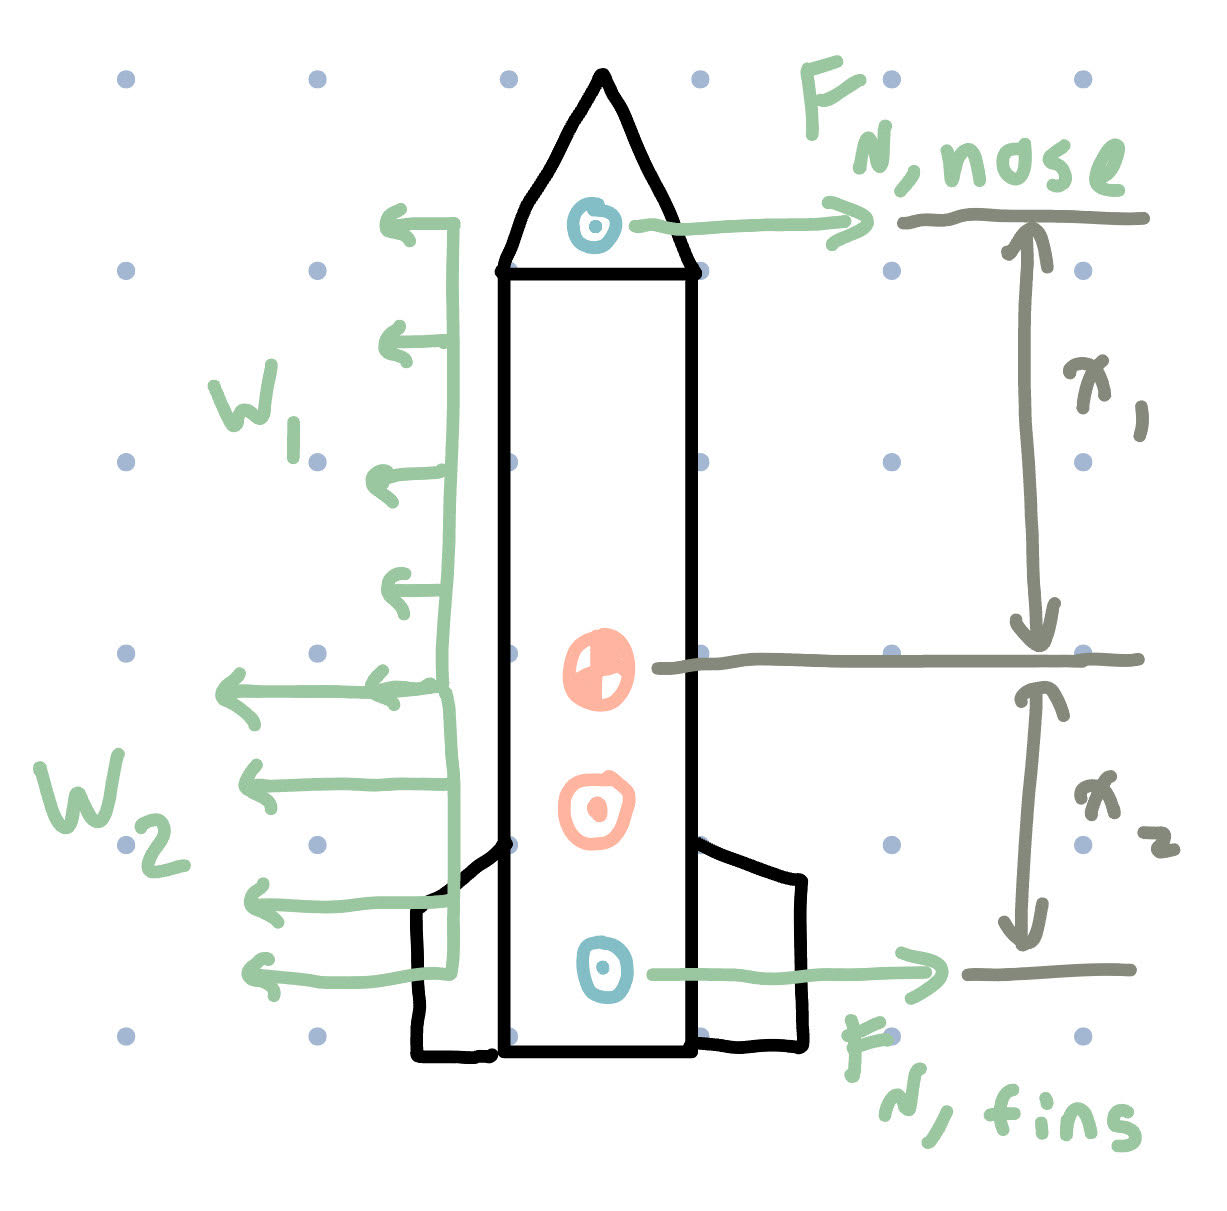

% Max drag calc
front_area = pi*((d/12)/2)^2

front_area = 0.0531

F_d = 0.5*rho*burn_v^2*cd*front_area

F_d = 63.9947


%Max dynamic pressure
q = 0.5*rho*burn_v^2

q = 1.6718e+03


% Fin geometry
theta = atand((1/S)*(Xr+0.5*(Ct-Cr)))

theta = 35.8377

Lf = S/(cosd(theta))

Lf = 5.5509


% Normal forces
Cn_alpha_fins = (1+(R/(S+R))) * ((4*N*(S/d)^2) / (1+sqrt(1+((2*Lf)/(Cr+Ct))^2)))

Cn_alpha_fins = 11.1987

Fn_fins = q*front_area*aoa*Cn_alpha_fins

Fn_fins = 173.9465


Fn_nose = q*front_area*aoa*Cn_alpha_nose

Fn_nose = 44.4391


% Center of pressure locations
Xn = 0.5*L_nose

Xn = 8.6250

Xf1 = xb;
Xf2 = (Xr*(Cr+2*Ct))/(3*(Cr+Ct));
Xf3 = (1/6)*((Cr+Ct)-((Cr*Ct)/(Cr+Ct)));
Xf = Xf1+Xf2+Xf3

Xf = 78.7320


% Lateral acting inertia loads (lbf)
x1 = Xcg-Xn

x1 = 41.1810

x2 = Xf-Xcg

x2 = 28.9260

W2 = (Fn_fins*(2*x2+x1)-Fn_nose*x1)/(x2^2+x1*x2) %for x1<=x<=x2

W2 = 7.5922

W1 = (Fn_nose+Fn_fins-W2*x2)/x1 %for 0<=x<=x1

W1 = -0.0298

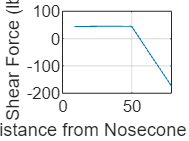


% Shear Loading and Moment Calcs
L_tot = x1+x2;
x = linspace(0,L_tot,100);
i = 1;
V = []; %matrix for shear force
M = []; %matrix for bending moment

while x(i) <= x1
    V(i) = Fn_nose-W1*x(i);
    M(i) = Fn_nose*x(i)-0.5*W1*(x(i))^2;
    i = i+1;
end

V1 = Fn_nose-W1*x1;

while x(i) < L_tot
    V(i) = V1-W2*(x(i)-x1);
    M(i) = V1*x(i)-0.5*W2*(x(i))^2+W2*x1*x(i)+0.5*W2*(L_tot)^2-L_tot*(V1+W2*x1);
    i = i+1;
end

V(i) = V1-W2*(L_tot-x1); %these are here to get last V&M values because loop was being stupid
M(i) = V1*L_tot-0.5*W2*(L_tot)^2+W2*x1*L_tot+0.5*W2*(L_tot)^2-L_tot*(V1+W2*x1);

% The previous calcs were done using a relative coordinate system
% The following plots shear and moment w.r.t. true coordinates
% Nosecone tip is x=0 in
x_true = x+Xn;

plot(x_true,V)
hold on
xlabel('Distance from Nosecone Tip (in)')
ylabel('Shear Force (lbf)')
grid on
hold off

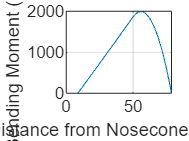


plot(x_true,M)
hold on
xlabel('Distance from Nosecone Tip (in)')
ylabel('Bending Moment (lbf*in)')
grid on
hold off



% Finding max compressive stress due to both bending and axial forces

% Max bending stress on rocket body:
d_out = d;
d_in = d-2*t;
z = (pi/(32*d))*(d_out^4-d_in^4)

z = 0.4329

M_max = max(M)/z;

% Max compressive stress due to drag:
A_cs = (pi/4)*(d_out^2-d_in^2);
Fc_drag = F_d/A_cs; %psi

% Max compressive stress due to mass inertia:
Fc_inertia = (m_wet*32.2*(1+a_max/32.2))/A_cs; %psi

% Max combined compressive stress:
Fc_total = M_max+Fc_drag+Fc_inertia %psi

Fc_total = 2.1380e+04


% Factor of safety
FS = Fy/Fc_total

FS = 1.6371

### Interpretation of Results

Use the bending and shear force graphs to find out where the maximum compressive force will be on the vehicle. Then, look at the maximum compressive stress (Fc_total) and make sure it does not exceed the yield stress or desired factor of safety. If it all looks good, then the vehicle will not fail by yielding.

### Determining Failure by Buckling

If it does not fail by yielding, then you also need to check if it will fail by buckling. You can use the chart below from Richard Nakka as a very conservative estimate of the critical buckling stress. If you land below the line, then the vehicle will not buckle. 

L = L_tot;
Dt_ratio = d_out/t

Dt_ratio = 52.0000

rt_ratio = (d_out/2)/t

rt_ratio = 26.0000

LR_ratio = L/(d_out/2)

LR_ratio = 44.9404

- Only use graph if D/t > 70

- L is the unsupported length of the rocket. Couplers can act as supports. Use the entire vehicle length for an ultra conservative estimate (though this is not realistic).

- The following graph is only to be used for aluminum tubing